% You can simply define your cost in a seperate file and load its handle to fobj 
% The initial parameters that you need are:
%__________________________________________
% fobj = @YourCostFunction
% dim = number of your variables
% Max_iteration = maximum number of generations
% SearchAgents_no = number of search agents
% lb=[lb1,lb2,...,lbn] where lbn is the lower bound of variable n
% ub=[ub1,ub2,...,ubn] where ubn is the upper bound of variable n
% If all the variables have equal lower bound you can just
% define lb and ub as two single number numbers

% To run ALO: [Best_score,Best_pos,cg_curve]=ALO(SearchAgents_no,Max_iteration,lb,ub,dim,fobj)
%__________________________________________

clear all 
clc

SearchAgents_no=5; % Number of search agents

Function_name='F6'; % Name of the test function that can be from F1 to F23 (Table 1,2,3 in the paper)

Max_iteration=500; % Maximum numbef of iterations

% Load details of the selected benchmark function
[lb,ub,dim,fobj]=Get_Functions_details(Function_name);

[Best_score,Best_pos,cg_curve]=ALO(SearchAgents_no,Max_iteration,lb,ub,dim,fobj);

At iteration 50 the elite fitness is 8384.2088
At iteration 100 the elite fitness is 1862.9217
At iteration 150 the elite fitness is 257.8487
At iteration 200 the elite fitness is 22.9959
At iteration 250 the elite fitness is 4.2386
At iteration 300 the elite fitness is 0.40678
At iteration 350 the elite fitness is 0.019928
At iteration 400 the elite fitness is 0.0061617
At iteration 450 the elite fitness is 6.4763e-05
At iteration 500 the elite fitness is 2.1607e-06


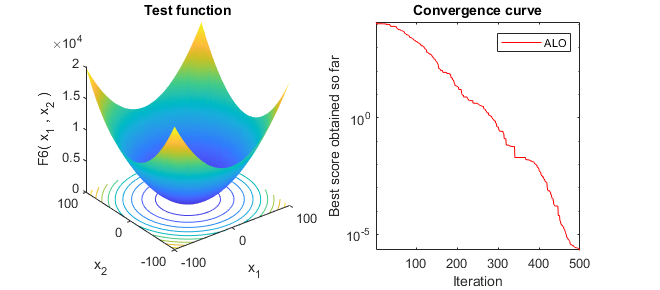


figure('Position',[500 500 660 290])
%Draw search space
subplot(1,2,1);
func_plot(Function_name);
title('Test function')
xlabel('x_1');
ylabel('x_2');
zlabel([Function_name,'( x_1 , x_2 )'])
grid off

%Draw objective space
subplot(1,2,2);
semilogy(cg_curve,'Color','r')
title('Convergence curve')
xlabel('Iteration');
ylabel('Best score obtained so far');

axis tight
grid off
box on
legend('ALO')


display(['The best solution obtained by ALO is : ', num2str(Best_pos)]);

The best solution obtained by ALO is : -0.49947    -0.49911    -0.50043    -0.49983    -0.49999    -0.49953    -0.50012    -0.50068    -0.50039    -0.49988


display(['The best optimal value of the objective funciton found by ALO is : ', num2str(Best_score)]);

The best optimal value of the objective funciton found by ALO is : 2.1607e-06
